EXERCICI 1:

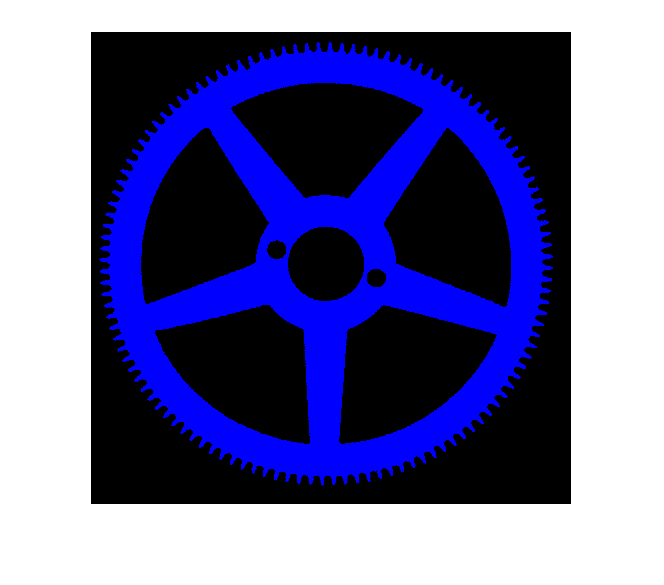

I = imread('wheel.bmp');
imshow(I);

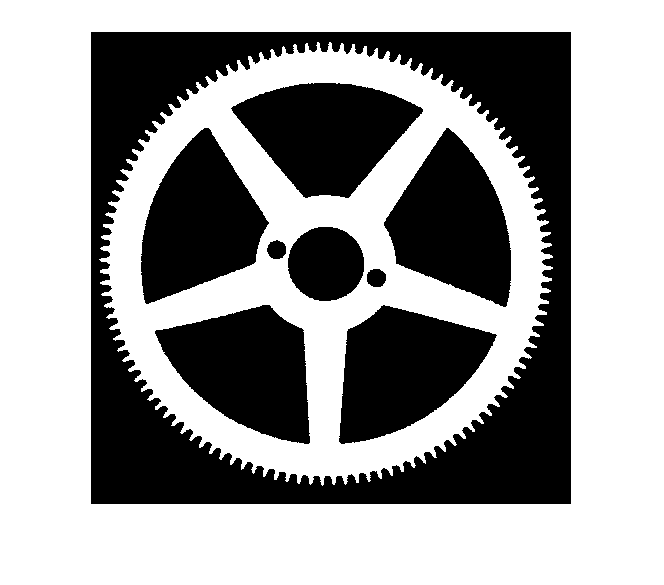

BW = rgb2gray(I);
B = BW > 28;
imshow(B);

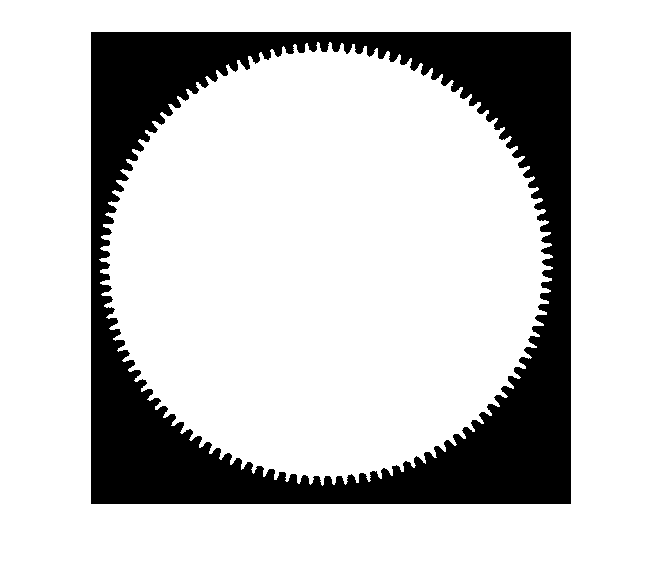

F = imfill(B, 'holes');
imshow(F);

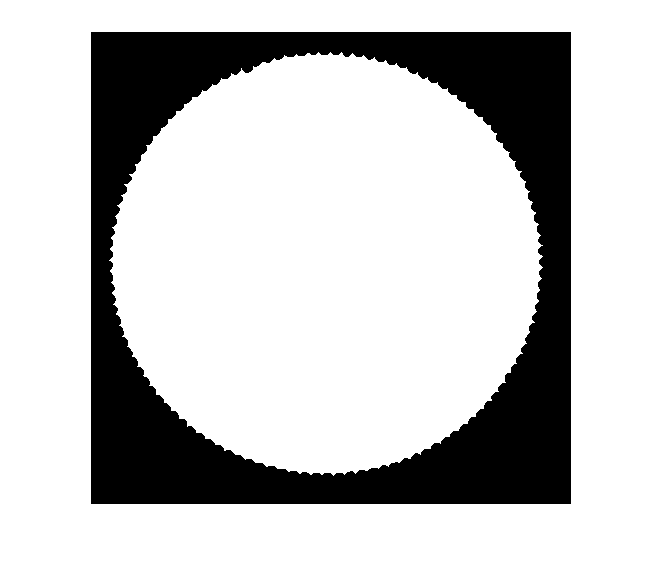

SE = strel('disk', 4);
A = imerode(F, SE);
imshow(A);

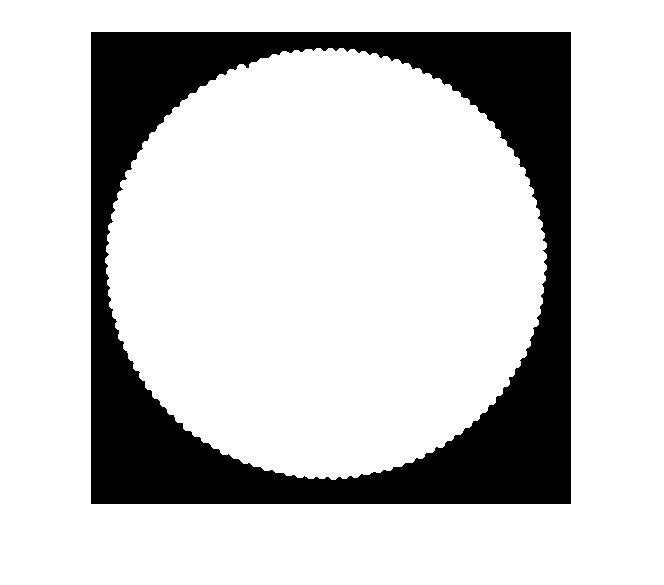

SE2 = strel('disk', 5);
B = imdilate(A, SE2);
imshow(B);

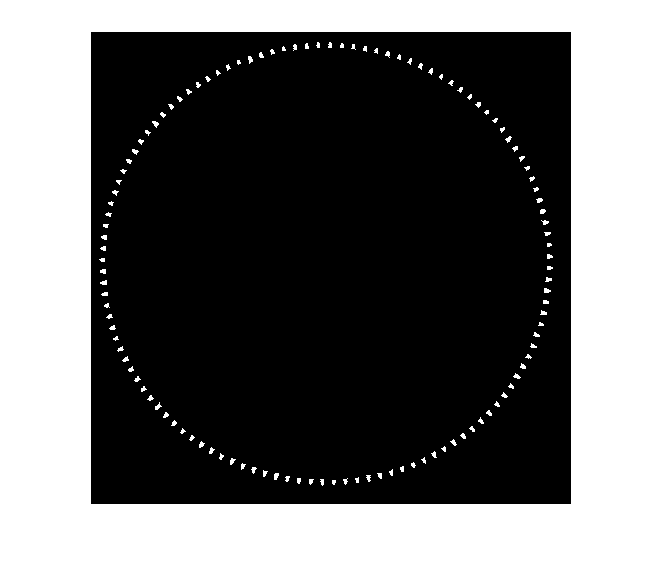

D = F & not(B);
imshow(D);

Label = bwconncomp(D);
Result = Label.NumObjects

Result = 120

EXERCICI 2: Executar el codi de l'exercici2.m

EXERCICI 3:

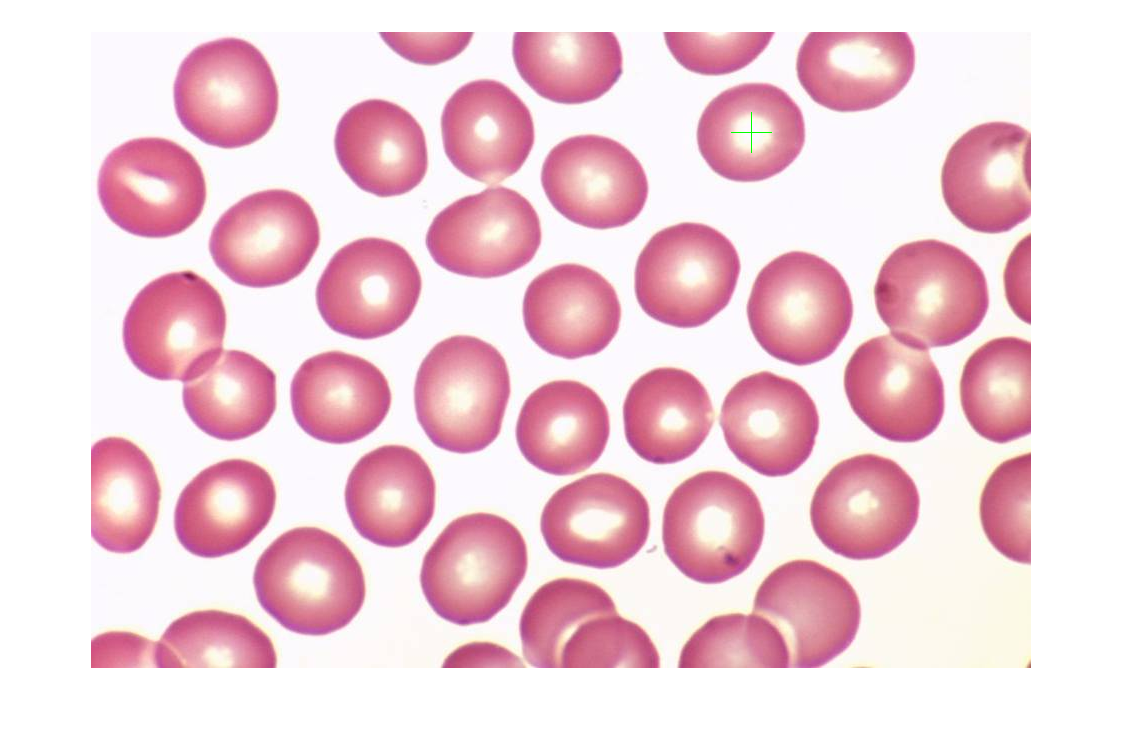

S = bwmorph(Fnew, 'shrink', Inf); % punts
imshow(S);
D = bwdist(S);
DL = watershed(D);
S2 = DL == 0; % vores
imshow(S2);
BWd = bwdist(S2, 'euclidean');
imshow(BWd, []);
And = S .* BWd;
imshow(And);
[r x] = max(max(And));
[r y] = max(And(:,661));
J = insertMarker(I2,[x y],'+', 'size', 20);
imshow(J);